# Gabriel Colangelo

clear
close all
clc

## Problem 1a)

% Periapsis and Apoapsis
rp      = 1.8;  % Mars Radii
ra      = 8;    % Mars Radii

% Initial Mean Anomaly
M0      = -120; % [deg]


$$\underline{Find}: a,e,p, period,\epsilon,r_o,v_0, \theta_0^*, E_0, \gamma_0,t_0 - t_p$$


% Calculate Semi major axis
a       = (ra + rp)/2;
fprintf('The semi major axis %.1f Mars Radii', a)

The semi major axis 4.9 Mars Radii


$$a = \frac{r_a + r_p}{2} = 4.9 \ [R_{Mars}]$$


% Calculate Eccentricity 
e       = 1 - (rp/a);
fprintf('Eccentricity is %.3f', e)

Eccentricity is 0.633


$$r_p = a(1 -e ) \\
e = 1 - \frac{r_p}{a} = 0.63$$


% Calculate semi latus rectum
p       = rp*(1+e);
fprintf('Semi latus rectum is %.3f Mars Radii', p)

Semi latus rectum is 2.939 Mars Radii


$$r_p = \frac{p}{1+e} \\
p = r_p(1+e) = 2.94 \ [R_{Mars}]$$


% Mars gravitional constant
mu_mars = 42828.314258067; % [km^3/s^2]

% Mars Radius at equator
R_mars  = 3397 ;           % [km]

% Calculate period [s]
tau     = 2*pi*sqrt((a*R_mars)^3/mu_mars);
fprintf('The orbital period around mars is %.2f hours',tau/3600)

The orbital period around mars is 18.11 hours


$$period = 2\pi\sqrt{\frac{a^3}{\mu}} = 18.11 \ [hrs]$$


% Calculate specific energy
energy  = -mu_mars/(2*a*R_mars);
fprintf('The specific energy is %.3f km^2/s^2', energy)

The specific energy is -1.286 km^2/s^2


$$\epsilon = \frac{-\mu}{2a} = -1.29 \ [km^2/s^2]$$


% Calculate eccentric anomaly via newton raphson
E0      = CalcEccentricAnomaly(e,M0*pi/180)*180/pi;
fprintf('The initial eccentric anomaly is %.2f deg',E0)

The initial eccentric anomaly is -142.21 deg


$$M = E - e\sin{E} \\
E_0 = -142.2 \ [deg]$$


% Calclate true anomaly from eccentric anomaly
ta0     = 2*atand(sqrt((1+e)/(1-e))*tand(E0/2));
fprintf('The initial true anomaly is %.2f deg',ta0)

The initial true anomaly is -161.56 deg


$$\tan{\frac{\theta^*}{2}} = \sqrt{\frac{1+e}{1-e}} \tan{\frac{E}{2}} \\
\theta^*_0 = 2\tan^{-1}{( \sqrt{\frac{1+e}{1-e}} \tan{\frac{E_0}{2}})}= -161.6 \ [deg]$$


% Calculate Initial radius
r0      = a*(1 - e*cosd(E0));
fprintf('The initial radius is %.4f Mars radii',r0)

The initial radius is 7.3499 Mars radii


$$r_0 = a(1 - e\cos{E_0}) = 7.35 \ [R_{Mars}]$$


% Calculate initial velocity
v0      = sqrt(2*(energy + mu_mars/(r0*R_mars)));
fprintf('The initial velocity is %.3f km/s', v0)

The initial velocity is 0.926 km/s


$$\epsilon = \frac{v^2}{2} - \frac{\mu}{r} \\ 
v_0 = \sqrt{2(\epsilon + \frac{\mu}{r_0})} = 0.93 \ [km/s]$$


% Calculate angular momentum magnitude
h       = sqrt(mu_mars*p*R_mars);

% Calculate angular velocity from angular momentum magntiude
ta0dot  = h/((r0*R_mars)^2);

% Calculate radial component of velocity, use negative root due to sign of anomalys
r0dot   = -sqrt(v0^2 - (r0*R_mars)^2*ta0dot^2);

% Calculate flight path angle
gamma0  = atan2d(r0dot,(r0*R_mars)*ta0dot);
fprintf('The initial flight path angle is %.2f deg', gamma0)

The initial flight path angle is -26.59 deg


$$h =\sqrt{\mu p} = r^2\dot{\theta} \\
v^2 = \dot{r}^2 + r^2\dot{\theta}^2 \\
\tan{\gamma} = \frac{\dot{r}}{r \dot{\theta}} = \frac{v_r}{v_{\theta} \\
\gamma_0  =\ tan^{-1}{\frac{\dot{r}}{r \dot{\theta}}} = -26.6 \ [deg]$$


% Calculate time since periapsis - convert M to degrees and convert M  = -120 to 240
dtp     = (M0*pi/180 + 2*pi)/(sqrt(mu_mars/(a*R_mars)^3));
fprintf('The time since the last periapsis is %.1f hours',dtp/3600)

The time since the last periapsis is 12.1 hours


$$M = \sqrt{\frac{\mu}{a^3}}(t - t_p) \\
(t_0 - t_p)  = \frac{M_0}{ \sqrt{\frac{\mu}{a^3}}} = 12.1 \ [hrs]$$


## Problem 1b)


$$\underline{Find}: \bar{r}_0, \bar{v}_0, \ in \ \hat{r},\ \hat{\theta},  \ and \ \hat{e},\hat{p}$$


% Define r0 and v0 in orbit frame
v0_O    = [r0dot; (r0*R_mars)*ta0dot;0];
r0_O    = [r0;0;0];


$$\bar{v}_0 = \dot{r}\hat{r} + r\dot{\theta} \hat{\theta}  = -0.415 \ \hat{r} + 0.828 \ \hat{\theta} \ [km/s]\\
\bar{r}_0  = 7.35 \ \hat{r} \ [R_{mars}]$$


% DCM matrix from rotating orbit frame to perifocal frame
P_DCM_O = [cosd(ta0), -sind(ta0), 0;...
           sind(ta0), cosd(ta0), 0;...
           0, 0, 1];

% Rotate vectors into perifocal frame
r0_P    = P_DCM_O*r0_O;
v0_P    = P_DCM_O*v0_O;


$$[r_0]^P = [PO] [r_0]^O \\
[v_0]^P = [PO] [v_0]^O \\
\bar{r}_0 =-6.97 \ \hat{e} -2.32 \ \hat{p}\ [R_{mars}] \\
\bar{v}_0 =  0.655 \ \hat{e} -0.654 \ \hat{p} \ [km/s]$$


## Problem 1c)


$$\underline{Find}: \theta^*_1, r_1, v_1, E_1, \gamma_1, (t_1 - t_p) $$


% Mean motion
n       = sqrt(mu_mars/(a*R_mars)^3);

% Change in time
dt      = 0.75*tau;

% Calculate mean anomaly for time equal to 75% of period from t0
M1      = M0*(pi/180) + n*dt;

% Calculate eccentric anomaly from mean anomaly
E1      = CalcEccentricAnomaly(e,M1)*180/pi;
fprintf('The eccentric anomaly at new time is %.2f deg',E1)

The eccentric anomaly at new time is 161.50 deg


$$n = \sqrt{\frac{\mu}{a^3}} \\
M_1 = M_0 +  n(t_1 - t_0) \\
M = E - e\sin{E} \\
E_1 = 161.5 \ [deg]
$$


% Calclate true anomaly from eccentric anomaly
ta1     = 2*atand(sqrt((1+e)/(1-e))*tand(E1/2));
fprintf('The true anomaly at new time is %.2f deg',ta1)

The true anomaly at new time is 171.17 deg


$$\tan{\frac{\theta^*}{2}} = \sqrt{\frac{1+e}{1-e}} \tan{\frac{E}{2}} \\
\theta^*_1 = 2\tan^{-1}{( \sqrt{\frac{1+e}{1-e}} \tan{\frac{E_1}{2}})}= 171.2 \ [deg]$$


% Calculate Initial radius
r1      = a*(1 - e*cosd(E1));
fprintf('The radius at new time is %.4f Mars radii',r1)

The radius at new time is 7.8398 Mars radii


$$r_1 = a(1 - e\cos{E_1}) = 7.84 \ [R_{Mars}]$$


% Calculate initial velocity
v1      = sqrt(2*(energy + mu_mars/(r1*R_mars)));
fprintf('The velocity at new time is %.3f km/s', v1)

The velocity at new time is 0.802 km/s


$$\epsilon = \frac{v^2}{2} - \frac{\mu}{r} \\ 
v_1 = \sqrt{2(\epsilon + \frac{\mu}{r_1})} = 0.80 \ [km/s]$$


% Calculate angular velocity from angular momentum magntiude
ta1dot  = h/((r1*R_mars)^2);

% Calculate radial component of velocity, use positive root due to sign of anomalys
r1dot   = sqrt(v1^2 - (r1*R_mars)^2*ta1dot^2);

% Calculate flight path angle
gamma1  = atan2d(r1dot,(r1*R_mars)*ta1dot);
fprintf('The flight path angle at the new time is %.2f deg', gamma1)

The flight path angle at the new time is 14.53 deg


$$h = r^2\dot{\theta} \\
v^2 = \dot{r}^2 + r^2\dot{\theta}^2 \\
\tan{\gamma} = \frac{\dot{r}}{r \dot{\theta}} = \frac{v_r}{v_{\theta} \\
\gamma_1  =\ tan^{-1}{\frac{\dot{r_1}}{r_1 \dot{\theta_1}}} = 14.5 \ [deg]$$


% Calculate time since periapsis - convert M to degrees
dtp1    = M1/(sqrt(mu_mars/(a*R_mars)^3));
fprintf('The time since the last periapsis is %.1f hours',dtp1/3600)

The time since the last periapsis is 7.5 hours


$$M = \sqrt{\frac{\mu}{a^3}}(t - t_p) \\
(t_1 - t_p)  = \frac{M_1}{ \sqrt{\frac{\mu}{a^3}}} = 7.5 \ [hrs]$$


% Calculate change in true anomaly and eccentric anomaly
dta     = ta1 - ta0;
fprintf('The change in true anomaly is %.1f degrees', dta)

The change in true anomaly is 332.7 degrees


$$\Delta\theta^* = \theta^*_1 - \theta^*_0= 332.7 \ [deg]$$


dE      = E1 - E0;
fprintf('The change in eccentric anomaly is %.1f degrees', dE)

The change in eccentric anomaly is 303.7 degrees


$$\Delta E = E_1 - E_0  = 303.7 \ [deg]$$


## Problem 1d)


$$\underline{Find}: \bar{r}_1, \bar{v}_1 $$


% Calculate f, g, fdot, and gdot using eccentric anomaly
f1      = (1 - (a/r0)*(1 - cosd(E1 - E0)));
g1      = dt - sqrt((a*R_mars)^3/mu_mars)*(E1*(pi/180) - E0*(pi/180) - sind(E1 - E0));
f1dot   =  -sqrt(mu_mars*a*R_mars)*sind(E1 - E0)/(r1*r0*R_mars*R_mars);
g1dot   = (1 - (a/r1)*(1 - cosd(E1 - E0)));

Note: f and $\dot{g}$ are unitless, while g has units of [sec] and $\dot{f}$ has units of $[sec]^{-1}$


$$f       = 1 - \frac{a}{r_0}[1 - \cos{(E_1- E_0)}] \\

g          = (t_1 - t_0) - \sqrt{\frac{a^3}{\mu}}[E_1 - E_0 - \sin{(E_1 - E_0})] \\

\dot{f}= -\frac{\sqrt{\mu a}}{r_1 r_0} \sin{(E_1 - E_0)} \\

\dot{g}  =  1 - \frac{a}{r_1}[1 - \cos{(E_1- E_0)}] \\

\bar{r}_1 = f \ \bar{r}_0 + g \ \bar{v}_0 =  0.703 \ \bar{r}_0 \ [R_{mars}] - 1.474 \times 10^4 \ \bar{v}_0 \ [km/s]\\
\bar{v}_1 = \dot{f} \ \bar{r}_0 + \dot{g} \ \bar{v}_0 = 3.34 \times 10^{-5} \ \bar{r}_0  \ [R_{mars}] +  0.722\  \bar{v}_0  \ [km/s] \\$$


## Problem 1e) Plot Orbit

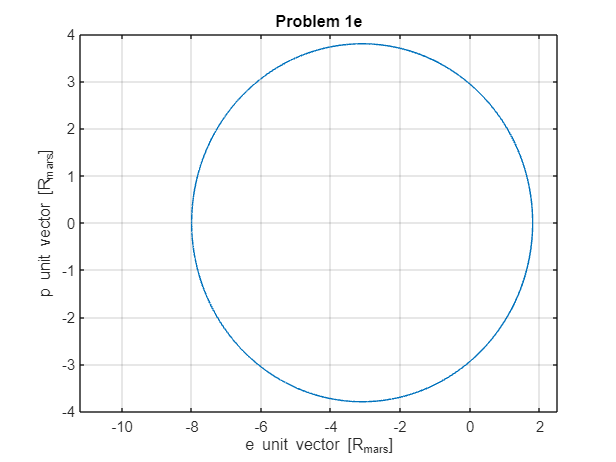

% Define time - increment by 10 second
time    = 0:10:tau;

% Initialize Perifocal position and velocity vector
r_P     = zeros(3,length(time)); 

% Calculate vectors in perifocal coordinates for each time step using f & g
% relations
for i = 1:length(time)

    % Calculate Mean Anonamly 
    M           = (M0*pi/180) + n*(time(i)- time(1));

    % Calculate Eccentric anomaly [rad]
    E           = CalcEccentricAnomaly(e, M);

    % Calculate f & g relations
    f       = (1 - (a/r0)*(1 - cosd(E*(180/pi) - E0)));
    g       = (time(i)- time(1)) - sqrt((a*R_mars)^3/mu_mars)*(E - E0*(pi/180) - sind(E*(180/pi) - E0));

    % Calculate perifocal position vector, convert r0 to km to be consistent with v0 in km/s
    r_P(:,i) = f*(r0_P*R_mars) + g*v0_P;
end

figure
plot(r_P(1,:)/R_mars,r_P(2,:)/R_mars)
xlim([-ra*1.4 rp*1.4])
title('Problem 1e')
grid on
xlabel('e unit vector [R_{mars}]')
ylabel('p unit vector [R_{mars}]')

function E = CalcEccentricAnomaly(e,M)
    % Input M in rad and output E in rad

    % Define error tolerance
      etol = 1e-8;

    % Initialize change in Eccentric Anomaly
      dE   = 1;
     
    % Initialize Eccentric Anomaly and counter
      count= 0;
      E    = M;

      while dE > etol
          % Increase counter
          count = count + 1;

          % Newton Raphson
          Enp1 = E - (E - e*sin(E) - M)/(1 - e*cos(E));

          % Assign new values and calculate delta
          dE   = abs(Enp1 - E);
          E    = Enp1;

          if count > 1000
              disp('Max iterations reached');
              break
          end
      end
end
